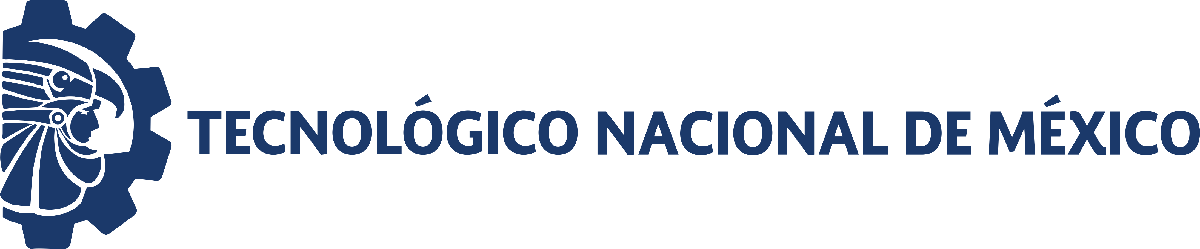                                 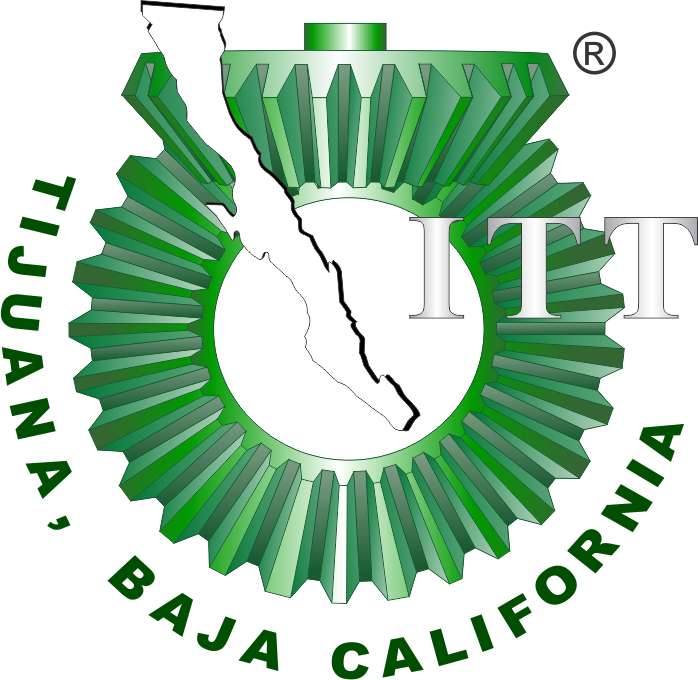

# Proyecto final: Dinámica inmunológica

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre de los alumnos: **Bricia Idalia Arellano Salones; Alberto Villalobos Valdez**

Número de control: **22211746; 22212277**

Correo institucional: **L22211746@tectijuana.edu.mx; L22212277@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Analizar datos obtenidos de tres variables biológicas y describir el comportamiento observado. El modelo matemático está compuesto por las siguientes tres EDOs de primer orden


$$\dot x = a_1 x^2yz-a_2x-a_3x^2y
$$



$$\dot y = b_1y-b_2y^2-b_3y^3$$



$$\dot z = c_1xz - c_2 z - c_3y^2z^2 + \rho_i$$


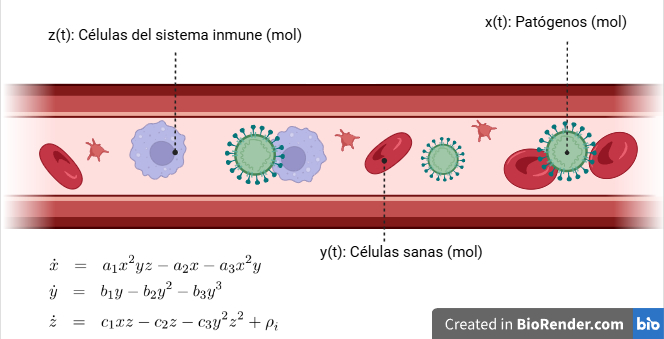

Figura. Diagrama representativo del modelo.

## Referencia

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

## Datos experimentales

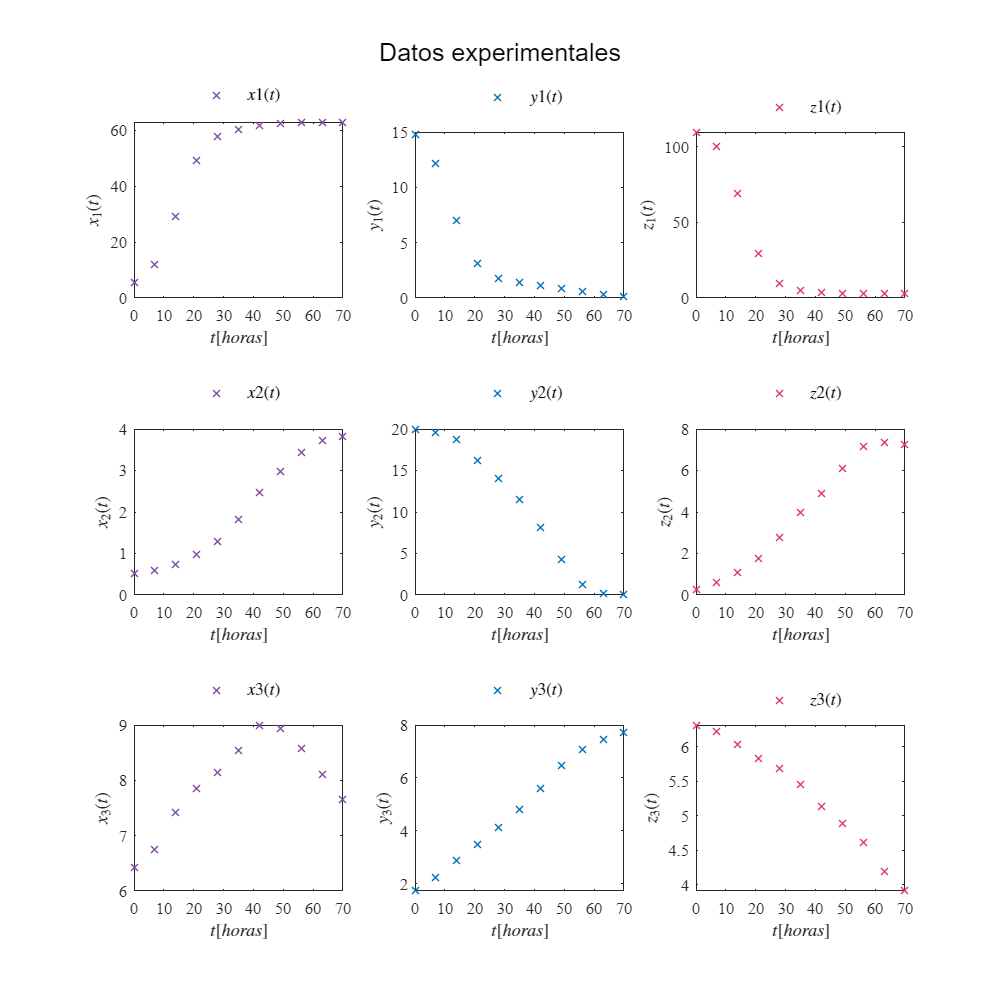

clc; clear; close all; warning('off','all') 
[t,x0,y0,z0] = getdata('data.csv');
plotdataraw(t,x0,y0,z0); sgtitle('Datos experimentales');...
    exportgraphics(gcf,'dataraw.pdf', 'ContentType','vector');

## Datos normalizados

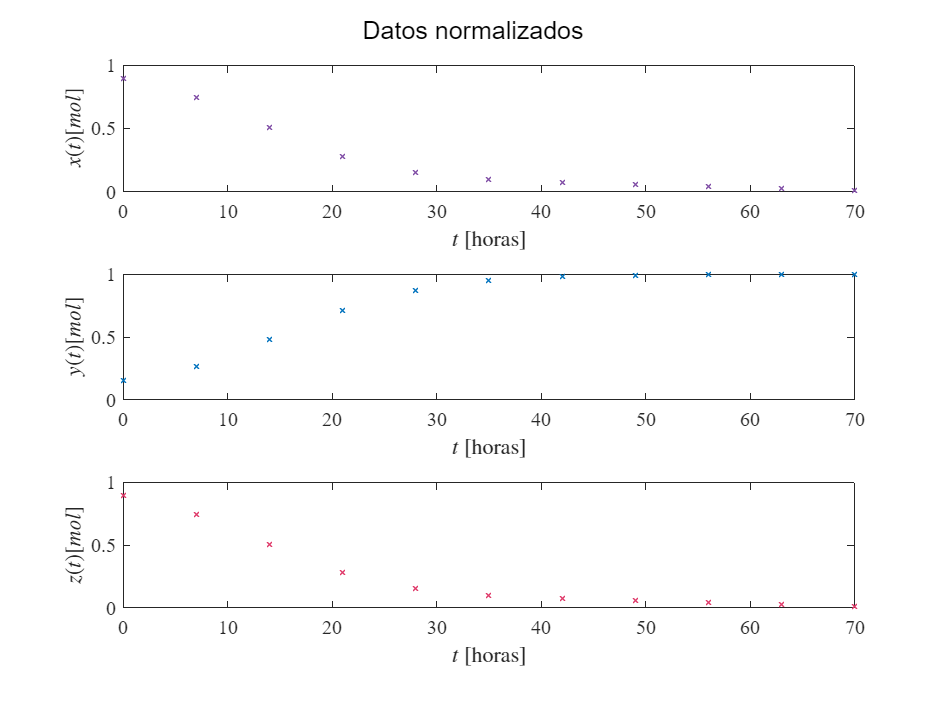

smooth = true; normalize = true;
[t,xo,yo,zo]=getdatanorm('data.csv',smooth,normalize);
plotsys(t,xo,yo,zo); sgtitle('Datos normalizados');...
    exportgraphics(gcf,'data_normalized.pdf', 'ContentType','vector');

## Modelo ODE 89 

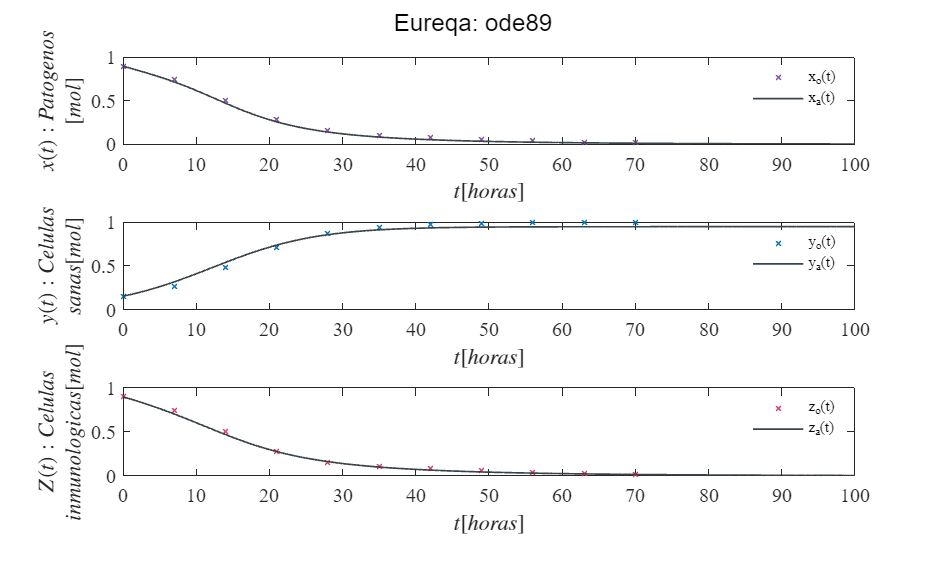

r1 = [0.59325246999979,0.1353100902857607,0.0246924900245628]; 
r2 = [0.043825801274132,0.1356158572160787,0.0431513991137263]; 
r3 = [0.408829201330716,0.0070631189682756,0.278932709148436];  
[t0,solV] = ode89(@(t,V) sysODE(V,[r1',r2',r3']), [0, 100], [xo(1),yo(1),zo(1)]);
x1 = solV(:,1);
y1 = solV(:,2);
z1 = solV(:,3);
plotresults(t,xo,yo,zo,t0,x1,y1,z1); sgtitle('Eureqa: ode89');...
   exportgraphics(gcf, 'Eureqa_ode89.pdf', 'ContentType', 'vector');

## Modelo a 2t: Método de Heun 

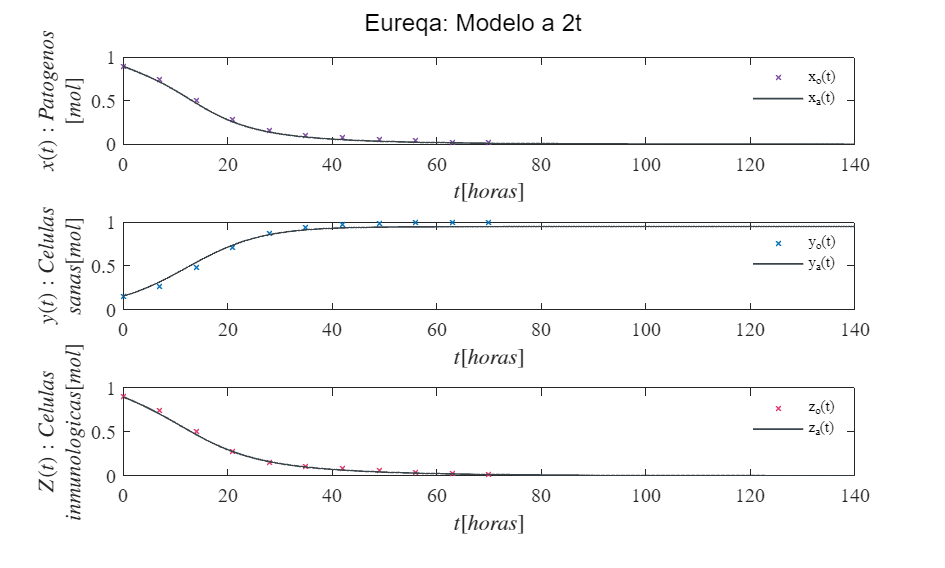

dt= 1e-4; tend = t(end); 
[th,xh,yh,zh] = sysheun(xo(1),yo(1),zo(1),[r1', r2', r3'],2*tend,dt);
plotresults(t,xo,yo,zo,th,xh,yh,zh); sgtitle('Eureqa: Modelo a 2t');...
   exportgraphics(gcf, 'Eureqa2t.pdf', 'ContentType', 'vector');

## Puntos de equilibrio del sistema

a1 = r1(1); a2 = r2(1); a3 = r3(1); b1 = r1(2); b2 = r2(2); b3 = r3(2); 
c1 = r1(3) ; c2 = r2(3); c3 = r3(3);
syms x y z 
dx_dt = a1*y*z*x^2 - a2*x - a3*y*x^2 == 0;
dy_dt = b1*y - b2*y^2 - b3*y^3 == 0;
dz_dt = c1*x*z - c2*z - c3*y^2*z^2 == 0;
fxyz = vpasolve([dx_dt, dy_dt dz_dt], [x,y, z]);
fprintf(['Puntos de equilibrio del sistema: ', num2str(length(fxyz.x))]);

Puntos de equilibrio del sistema: 11

xe_1 = fxyz.x(1); ye_1 = fxyz.y(1); ze_1 = fxyz.z(1);
xe_2 = fxyz.x(2); ye_2 = fxyz.y(2); ze_2 = fxyz.z(2);
fprintf('Puntos de equilibrio simbólicos: ');...
    disp([xe_1, ye_1, ze_1;xe_2, ye_2, ze_2;]) 

Puntos de equilibrio simbólicos: 

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0.0053167586635061989981886141445988 & -20.1512372257748140443199640923 & -0.00037981200853065547842428145485688 \end{array}\right)$$

for i = 1: 11
    disp([fxyz.x(i); fxyz.y(i); fxyz.z(i)])
end

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0.0053167586635061989981886141445988\\ -20.1512372257748140443199640923\\ -0.00037981200853065547842428145485688 \end{array}\right)$$

$$\left(\begin{array}{c} 3162.8575779489991182729584402938\\ -20.1512372257748140443199640923\\ 0.68913074008918985477776476226974 \end{array}\right)$$

$$\left(\begin{array}{c} 8.8725605900597926463114960397592\\ 0.95067472283453777326533981108738\\ 0.69788998886909623409225648679485 \end{array}\right)$$

$$\left(\begin{array}{c} -0.089414477068945565899700388824909\\ 0.95067472283453777326533981108738\\ -0.1799296238570286477499277789709 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ -20.1512372257748140443199640923\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0.95067472283453777326533981108738\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0.0053196889716073454053284061762884\\ -20.1512372257748140443199640923\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ -20.1512372257748140443199640923\\ -0.00038097107664345592198489341711844 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0.95067472283453777326533981108738\\ -0.17117153414523506887899666640805 \end{array}\right)$$

$$\left(\begin{array}{c} -0.11276024476024197156136739468862\\ 0.95067472283453777326533981108738\\ 0 \end{array}\right)$$

## Matriz Jacobiana

dx_dt = a1*y*z*x^2 - a2*x - a3*y*x^2;
dy_dt = b1*y - b2*y^2 - b3*y^3;
dz_dt = c1*x*z - c2*z - c3*y^2*z^2;
J = jacobian([dx_dt, dy_dt, dz_dt],[x, y, z]);
fprintf('Matriz Jacobiana: \n'); disp(J);

Matriz Jacobiana: 


$$\left(\begin{array}{ccc} \frac{5343543205655361\,x\,y\,z}{4503599627370496}-\frac{920601519385595\,x\,y}{1125899906842624}-\frac{6315963593196617}{144115188075855872} & \frac{5343543205655361\,x^{2}\,z}{9007199254740992}-\frac{920601519385595\,x^{2}}{2251799813685248} & \frac{5343543205655361\,x^{2}\,y}{9007199254740992}\\ 0 & -\frac{24429665244364395\,y^{2}}{1152921504606846976}-\frac{4886076192190899\,y}{18014398509481984}+\frac{152345618047605}{1125899906842624} & 0\\ \frac{3558562843951063\,z}{144115188075855872} & -\frac{5024804979929357\,y\,z^{2}}{9007199254740992} & -\frac{5024804979929357\,z\,y^{2}}{9007199254740992}+\frac{3558562843951063\,x}{144115188075855872}-\frac{3109385999505493}{72057594037927936} \end{array}\right)$$

## Estabilidad en lazo abierto

[E,lambda] = equilibria;

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
eq2        ( 5.317e-03 ,-2.015e+01 ,-3.798e-04)
eq3        ( 3.163e+03 ,-2.015e+01 , 6.891e-01)
eq4        ( 8.873e+00 , 9.507e-01 , 6.979e-01)
eq5        (-8.941e-02 , 9.507e-01 ,-1.799e-01)
eq6        ( 0.000e+00 ,-2.015e+01 , 0.000e+00)
eq7        ( 0.000e+00 , 9.507e-01 , 0.000e+00)
eq8        ( 5.320e-03 ,-2.015e+01 , 0.000e+00)
eq9        ( 0.000e+00 ,-2.015e+01 ,-3.810e-04)
eq10       ( 0.000e+00 , 9.507e-01 ,-1.712e-01)
eq11       (-1.128e-01 , 9.507e-01 , 0.000e+00)


Equilibria |  lambda 1        |  lambda 2        |  lambda 3       | stability |
---------------------------------------------------------------------------------
eq1        -4.4e-02+0.0e+00i -4.3e-02+0.0e+00i +1.4e-01+0.0e+00i unstable  
eq2        +4.4e-02+0.0e+00i +4.3e-02+0.0e+00i -3.0e+00+0.0e+00i unstable  
eq3        -3.9e+01+1.4e+03i -3.9e+01-1.4e+03i -3.0e+00+

## Simulink: Tratamiento z(t)

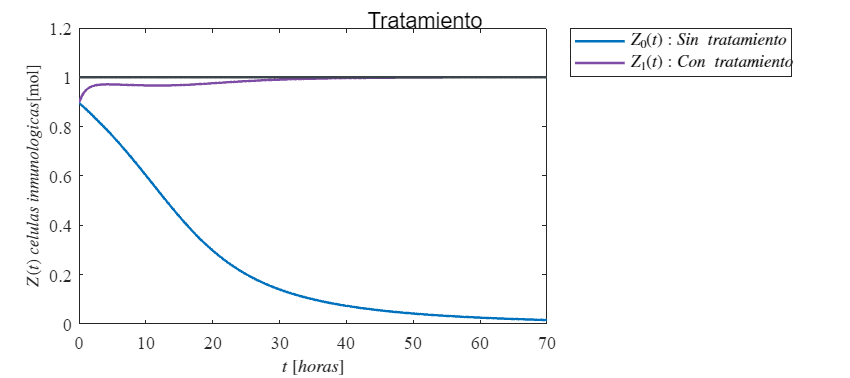

file = 'Sistema';
sim(file); 
parameters.StopTime = '70';
parameters.Solver = 'ode8'; 
parameters.FixedStep ='1E-3';
f = sim(file, parameters); 
plott(f.t,f.z,f.PI); sgtitle('Tratamiento');...
exportgraphics(gcf, 'tratamiento.pdf', 'ContentType', 'vector');

## Funciones

function plotdataraw(t,x,y,z)
set(figure(), 'color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [1 1 25 25])
FS = 10;
mycolors = [0.4980,    0.2980,    0.6471;
            0,         0.447,     0.741;
            0.8745,    0.2235,    0.4118];

% x %
subplot (3, 3, 1); box on; hold on;
plot (t,x(:,1), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,4); box on; hold on;
plot (t,x(:,2), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,7); box on; hold on;
plot (t,x(:,3), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

% y $
subplot (3, 3, 2); box on; hold on;
plot (t,y(:,1), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,5); box on; hold on;
plot (t,y(:,2), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t  [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,8); box on; hold on;
plot (t,y(:,3), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

% z %
subplot (3, 3, 3); box on; hold on;
plot (t,z(:,1), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,6); box on; hold on;
plot (t,z(:,2), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,9); box on; hold on;
plot (t,z(:,3), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)
end

function plotsys(to,xo,yo,zo)
    mycolors = [0.4980,    0.2980,    0.6471;
                0,         0.447,     0.741;
                0.8745,    0.2235,    0.4118];
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(3,1,1)
    hold on; box on; grid off;
    plot(to,xo,'x','LineWidth',1,'MarkerSize',4,'Color', mycolors(1,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
    ylabel('$x(t) [mol]$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,2)
    hold on; box on; grid off;
    plot(to,yo,'x','LineWidth',1,'MarkerSize',4,'Color',mycolors(2,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
    ylabel('$y(t) [mol]$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,3)
    hold on; box on; grid off;
    plot(to,zo,'x','LineWidth',1,'MarkerSize',4,'Color', mycolors(3,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
    ylabel('$z(t) [mol]$','Interpreter','Latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function plotresults(to,xo,yo,zo,ta,xa,ya,za)
    mycolors = [0.2314,    0.2667,    0.2941;
                0.4980,    0.2980,    0.6471;
                0,         0.447,     0.741;
                0.8745,    0.2235,    0.4118];

set( figure(), 'Color', 'w')
FS = 12; 
set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,12])
subplot (3,1,1)
hold on; box on; grid off;
plot(to,xo,'x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(2, :))
plot(ta, xa, '-', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(1, :))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ({'$x(t): Patogenos$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('x_{o}(t)', 'x_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)
subplot (3,1,2)
hold on; box on; grid off; 
plot(to,yo,'x', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(3,:))
plot(ta, ya, '-', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(1,:))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ({'$y(t): Celulas$', ' $sanas[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('y_{o}(t)', 'y_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)
subplot (3,1,3)
hold on; box on; grid off; 
plot(to,zo,'x', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(4,:))
plot(ta, za, '-', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(1,:))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ({'$Z(t): Celulas$','$inmunologicas[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('z_{o}(t)', 'z_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)

end

function plott(t,Pp0,Pp1)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [0,         0.447,     0.741;
                0.4980,    0.2980,    0.6471;
                0.2314,    0.2667,    0.2941;
                0.8745,    0.2235,    0.4118];
    colororder(mycolors);
    one = ones(length(Pp1),1);
    plot(t, Pp0, t, Pp1,t, one,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    L = legend('$Z_{0}(t): Sin\ tratamiento$','$Z_{1}(t): Con\ tratamiento$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[horas]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Z(t)$ $celulas$ $inmunologicas$[mol]', 'Interpreter', 'Latex', 'FontSize', 10);
    xlim([0,t(end)]);
end


### Datos experimentales

function [to,x,y,z] = getdata(file)
    sys = readmatrix(file);
    to = round(sys(:,1));
    x1 = sys(:,2); y1 = sys(:,3); z1= sys(:,4);
    x2 = sys(:,5); y2 = sys(:,6); z2= sys(:,7);
    x3 = sys(:,8); y3 = sys(:,9); z3= sys(:,10);
    x = [x1,x2,x3]; y = [y1,y2,y3]; z = [z1,z2,z3];
end

### Funciones

function dV = sysODE(V, par)
    dV =zeros(3,1);
    dV(1) = par(1,1)*V(2)*V(3)*V(1)^2 - par(1,2)*V(1) - par(1,3)*V(2)*V(1)^2;
    dV(2) = par(2,1)*V(2) - par(2,2)*V(2)^2 - par(2,3)*V(2)^3;
    dV(3) = par(3,1)*V(1)*V(3) - par(3,2)*V(3) - par(3,3)*V(2)^2*V(3)^2;
end
function [to,xo,yo,zo] = getdatanorm(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    xo = sys(:,3);
    yo = sys(:,2);
    zo= sys(:,3);
    if smooth == false && normalize == false
    return
    elseif smooth == true && normalize == false
    xo = smoothdata(xo,'gaussian',5);
    yo = smoothdata(yo,'gaussian',5);
    zo = smoothdata(yo,'gaussian',5);
    elseif smooth == false && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    zo = zo/max(zo);
    elseif smooth == true && normalize == true
    to = to - to(1);
    xo = xo/max(xo);
    yo = yo/max(yo);
    zo = zo/max(zo);
    xo = smoothdata(xo,'gaussian',5);
    yo = smoothdata(yo,'gaussian',5);
    zo = smoothdata(zo,'gaussian',5);
    end
end


## Función Heun

function [t,x,y,z] = sysheun(x0,y0,z0,par,tend,dt)
    n = round(tend/dt); 
    t = (0:dt:tend);
    x = zeros(length(t),1); x(1)= x0;
    y = zeros(length(t),1); y(1)= y0; 
    z = zeros(length(t),1); z(1)= z0;

    for i = 1:n
      [fx,fy,fz] = f(x(i), y(i),z(i));
      xn = x(i) + fx*dt;
      yn = y(i) + fy*dt;
      zn = z(i) + fz*dt;
      [fxn,fyn,fzn] = f(xn,yn,zn);
      x(i+1) = x(i) + (fx +fxn)*dt/2;
      y(i+1) = y(i) + (fy +fyn)*dt/2;
      z(i+1) = z(i) + (fz +fzn)*dt/2;
    end

    function [dx, dy,dz] = f(x,y,z)
        dx = par(1,1)*y*z*x^2 - par(1,2)*x - par(1,3)*y*x^2;
        dy = par(2,1)*y - par(2,2)*y^2 - par(2,3)*y^3;
        dz = par(3,1)*x*z - par(3,2)*z - par(3,3)*y^2*z^2;
    end
end

## Equilibrios

function [E,lambda] = equilibria
e1 = [0;0;0];
e2 = [0.0053167586635061989981886141445988; -20.1512372257748140443199640923; -0.00037981200853065547842428145485688];
e3 = [3162.8575779489991182729584402938; -20.1512372257748140443199640923; 0.68913074008918985477776476226974];
e4 = [8.8725605900597926463114960397592; 0.95067472283453777326533981108738; 0.69788998886909623409225648679485];
e5 = [-0.089414477068945565899700388824909; 0.95067472283453777326533981108738; -0.1799296238570286477499277789709];
e6 = [0; -20.1512372257748140443199640923; 0];
e7 = [0; 0.95067472283453777326533981108738; 0];
e8 = [0.0053196889716073454053284061762884; -20.1512372257748140443199640923; 0];
e9 = [0; -20.1512372257748140443199640923; -0.00038097107664345592198489341711844];
e10 = [0; 0.95067472283453777326533981108738; -0.17117153414523506887899666640805];
e11 = [-0.11276024476024197156136739468862; 0.95067472283453777326533981108738; 0];

E = [e1,e2,e3,e4,e5,e6,e7,e8,e9,e10,e11]; E = double(E)'; E(E>-1e-12 & E<1e-12) = 0;
names = {'eq1';'eq2';'eq3';'eq4';'eq5';'eq6';'eq7';'eq8';'eq9';'eq10';'eq11'};
fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria', ' x*', ' y*', ' z*');
fprintf('-------------------------------------------------\n');
for i = 1:length(E)
fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
end
x = E(:,1); y = E(:,2); z = E(:,3);lr = zeros(length(E),3); li = zeros(length(E),3); stability = cell(length(E),1);
for i = 1:length(E) 
J= [(5343543205655361*x(i)*y(i)*z(i))/4503599627370496 - (920601519385595*x(i)*y(i))/1125899906842624 - 6315963593196617/144115188075855872, (5343543205655361*x(i)^2*z(i))/9007199254740992 - (920601519385595*x(i)^2)/2251799813685248, (5343543205655361*x(i)^2*y(i))/9007199254740992;
    0, - (24429665244364395*y(i)^2)/1152921504606846976 - (4886076192190899*y(i))/18014398509481984 + 152345618047605/1125899906842624, 0; 
    (3558562843951063*z(i))/144115188075855872, -(5024804979929357*y(i)*z(i)^2)/9007199254740992, - (5024804979929357*z(i)*y(i)^2)/9007199254740992 + (3558562843951063*x(i))/144115188075855872 - 3109385999505493/72057594037927936];
lr(i,:) = real(eig(J)); lr(lr>-1e-12 & lr<1e-12) = 0;
li(i,:) = imag(eig(J));
if all(lr(i,:) < 0)
stability{i,1} = 'stable';
elseif any(lr(i,:) > 0)
stability{i,1} = 'unstable';
else
stability{i,1} = 'unidentified';
end
end
lambda = lr + 1i*li;

fprintf('\n\n%-10s | %-16s | %-16s | %-16s| %-10s|\n','Equilibria', ' lambda 1', ' lambda 2', ' lambda 3', 'stability');
fprintf('---------------------------------------------------------------------------------\n');
for i = 1:length(E)
fprintf('%-10s %+.1e%+.1ei %+.1e%+.1ei %+.1e%+.1ei %-10s\n', names{i}, real(lambda(i,1)),imag(lambda(i,1)), ...
real(lambda(i,2)),imag(lambda(i,2)), real(lambda(i,3)),imag(lambda(i,3)), stability{i});
end
end